# E/I ratio across directions for moving bar stimulus

Here data is only taken from cells that have voltage clamp recordings for both excitation and inhibition

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

us = {};
ds = {};

orientations = [0:45:315];

upPeakEx = cell(numel(orientations), 1);
upChargeEx = cell(numel(orientations), 1);
upPeakInh = cell(numel(orientations), 1);
upChargeInh = cell(numel(orientations), 1);

downPeakEx = cell(numel(orientations), 1);
downChargeEx = cell(numel(orientations), 1);
downPeakInh = cell(numel(orientations), 1);
downChargeInh = cell(numel(orientations), 1);


%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Intracellular', 'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    
    loc = loc_excitation;
    for j = 1:numel(orientations)
        indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
        upPeakEx{j} = [upPeakEx{j}, mean(loc.Analysis_Results.maxNegativePeakByEpoch(indices))];
        upChargeEx{j} =  [upChargeEx{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
    end
    
    loc = loc_inhibition;
    for j = 1:numel(orientations)
        indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
        upPeakInh{j} = [upPeakInh{j}, mean(loc.Analysis_Results.maxPositivePeakByEpoch(indices))];
        upChargeInh{j} =  [upChargeInh{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
    end
end



%downs second
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inhibition, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2
        continue
    end
    
    loc = loc_excitation;
    for j = 1:numel(orientations)
        indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
        downPeakEx{j} = [downPeakEx{j}, mean(loc.Analysis_Results.maxNegativePeakByEpoch(indices))];
        downChargeEx{j} =  [downChargeEx{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
    end
    
    loc = loc_inhibition;
    for j = 1:numel(orientations)
        indices = loc.Analysis_Results.orientationByEpoch  == orientations(j);
        downPeakInh{j} = [downPeakInh{j}, mean(loc.Analysis_Results.maxPositivePeakByEpoch(indices))];
        downChargeInh{j} =  [downChargeInh{j}, mean(loc.Analysis_Results.TotalChargeByEpoch(indices))];
    end
end


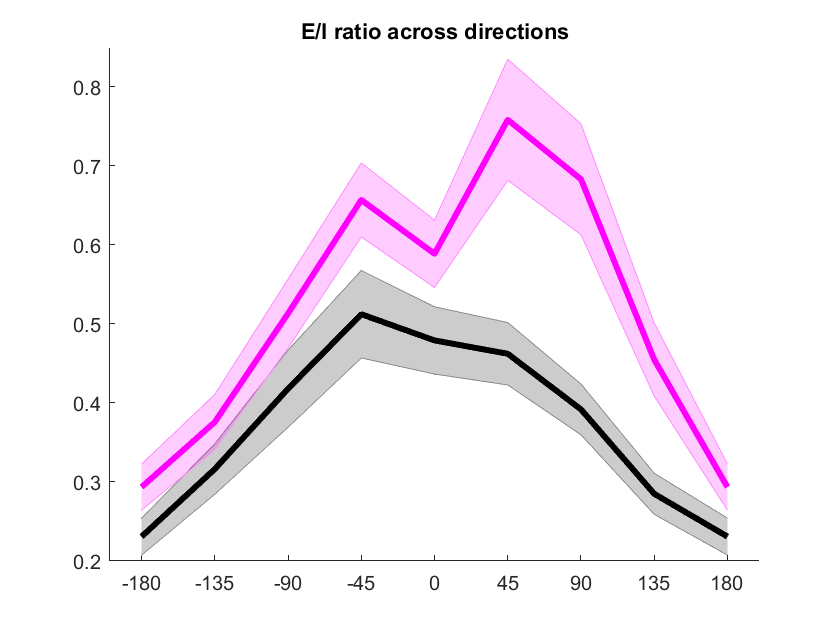

%Calculate E/I for each cell and each direction
ps = zeros(1, numel(orientations));
ms = zeros(2, numel(orientations));
es = zeros(2, numel(orientations));
upEtoIs = zeros(numel(upPeakEx{1}), numel(orientations));
downEtoIs = zeros(numel(downPeakEx{1}), numel(orientations));

dExRotated = [downPeakEx(5:8); downPeakEx(1:4)];
dInhRotated = [downPeakInh(5:8); downPeakInh(1:4)];

% dExRotated = [downPeakEx([1, 8:-1:2])];
% dInhRotated = [downPeakInh([1, 8:-1:2])];
for i = 1:numel(orientations)
    uExGroup = upPeakEx{i};
    uInhGroup = upPeakInh{i};
    uEtoI = -uExGroup./uInhGroup;
    upEtoIs(:, i) = uEtoI;
    
    dExGroup = dExRotated{i};
    dInhGroup = dInhRotated{i};
    dEtoI = -dExGroup./dInhGroup;
    downEtoIs(:, i) = dEtoI;
    
    ps(i) = ranksum(uEtoI, dEtoI);
    ms(1, i) = mean(uEtoI);
    ms(2, i) = mean(dEtoI);
    es(1, i) = std(uEtoI)/sqrt(numel(uEtoI));
    es(2, i) = std(dEtoI)/sqrt(numel(dEtoI));
end

curveOrientations = [-180:45:180];
scatterKey = [270, 315, 0:45:270];

figure
title('E/I ratio across directions')
hold on
% for i = 1:numel(curveOrientations)
%     thisOrientation = orientations == scatterKey(i);
%     scatter(zeros(size(upEtoIs, 1), 1) + curveOrientations(i), upEtoIs(:, thisOrientation), 'k', 'filled', 'MarkerFaceAlpha', 0.2)
%     scatter(zeros(size(downEtoIs, 1), 1) + curveOrientations(i), downEtoIs(:, thisOrientation), 'm', 'filled', 'MarkerFaceAlpha', 0.2)
% end
shadedErrorBar(curveOrientations, ms(1, [7:-1:1, 8, 7]), es(1, [7:-1:1, 8, 7]), 'LineProps', {'k', 'LineWidth', 3})
shadedErrorBar(curveOrientations, ms(2, [7:-1:1, 8, 7]), es(2, [7:-1:1, 8, 7]), 'LineProps', {'m', 'LineWidth', 3})
ylim([0.2, 0.85])
xticks([-180:45:180])

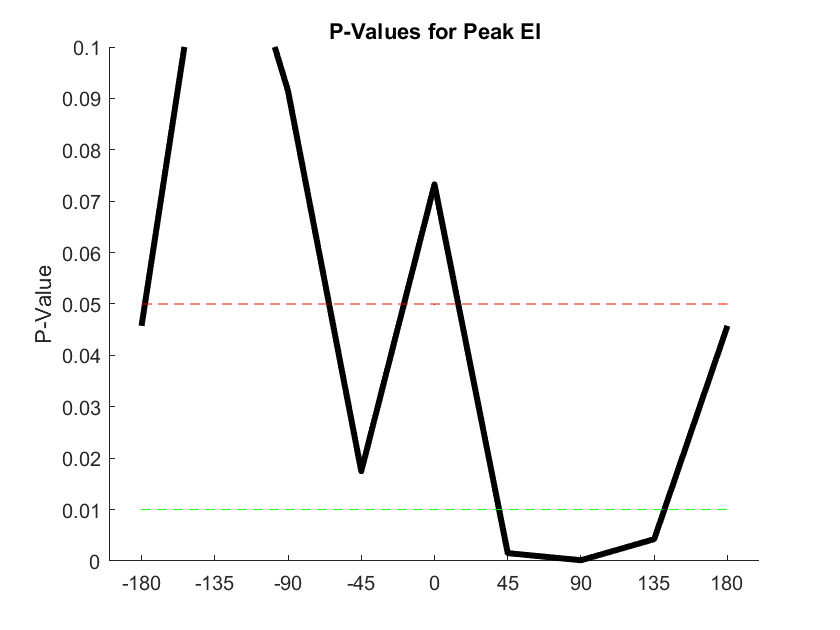


figure
title('P-Values for Peak EI')
hold on
plot(curveOrientations, ps([7:-1:1, 8, 7]), 'k', 'linewidth', 3)
plot(curveOrientations, zeros(size(curveOrientations))+0.01, '--g')
plot(curveOrientations, zeros(size(curveOrientations))+0.05, '--r')
ylim([0, 0.1])
ylabel('P-Value')
xticks([-180:45:180])

ps = ps([7:-1:1, 8, 7])

ps =     0.0457    0.1386    0.0915    0.0175    0.0733    0.0015    0.0002    0.0043    0.0457


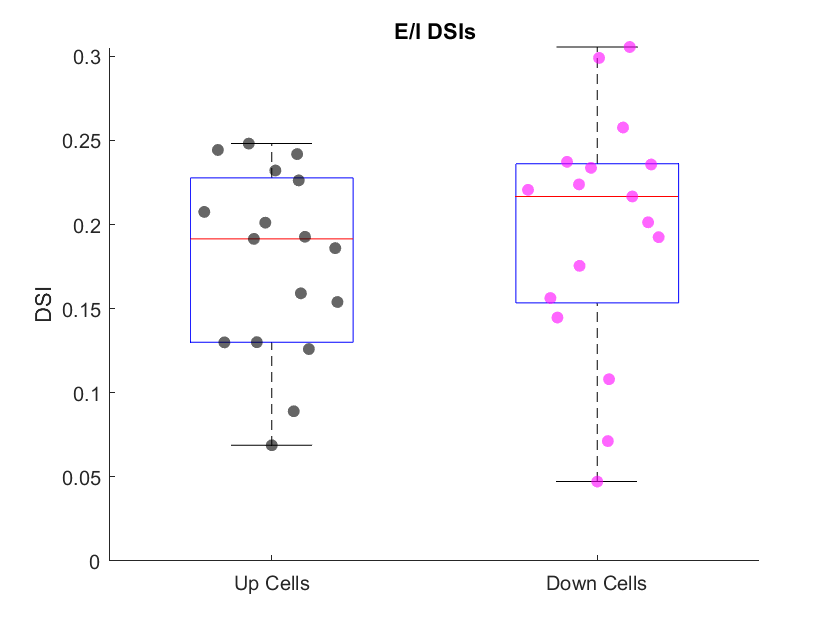

downEtoIs_unrotated = downEtoIs(:, [5:8, 1:4]);

upEtoI_DSIs = zeros(1, size(upEtoIs, 1));
downEtoI_DSIs = zeros(1, size(upEtoIs, 1));
thetas = [0:45:315];
for i = 1:size(upEtoIs, 1)
    upEtoI_DSIs(i) = calculateDSI(thetas, upEtoIs(i, :));
end

for i = 1:size(downEtoIs_unrotated, 1)
    downEtoI_DSIs(i) = calculateDSI(thetas, downEtoIs_unrotated(i, :));
end

groupIDs = zeros(1, numel([upEtoI_DSIs; downEtoI_DSIs]));
groupIDs(numel(upEtoI_DSIs)+ 1:end) = 1;

allDSIs = [upEtoI_DSIs, downEtoI_DSIs];


figure
title ('E/I DSIs')
hold on
boxplot(allDSIs, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(upEtoI_DSIs)), upEtoI_DSIs,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(downEtoI_DSIs))+1, downEtoI_DSIs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('DSI')
box off

p = ranksum(upEtoI_DSIs, downEtoI_DSIs)

p = 0.3892

## Average E/I across stimulus directions

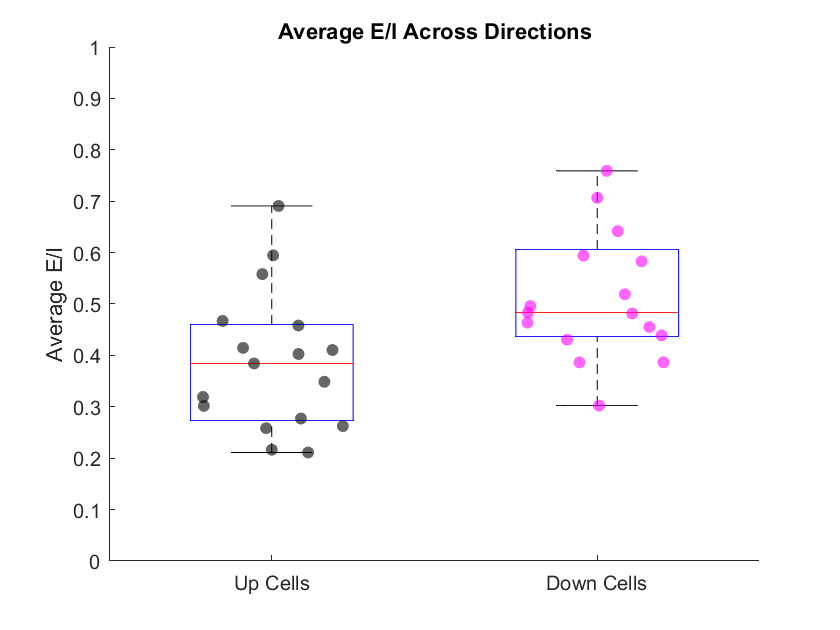


avgEIUp = zeros(1, numel(upPeakEx{1}));
for i = 1:numel(avgEIUp) %for each cell
    EtoI_perDirection = zeros(size(upPeakEx, 1), 1); %number of directions
    for j = 1:size(upPeakEx, 1) %for each direction
        ex_j = upPeakEx{j}; %grab the direction vector for excitation
        inh_j = upPeakInh{j}; %grab the direction vector for inhibition
        EtoI_perDirection(j) = -ex_j(i)/inh_j(i); %calculate E/I for that cell and that direction
    end
    avgEIUp(i) = mean(EtoI_perDirection);
end
avgEIDown = zeros(1, numel(downPeakEx{1}));
for i = 1:numel(avgEIDown) %for each cell
    EtoI_perDirection = zeros(size(downPeakEx, 1), 1); %number of directions
    for j = 1:size(downPeakEx, 1) %for each direction
        ex_j = downPeakEx{j}; %grab the direction vector for excitation
        inh_j = downPeakInh{j}; %grab the direction vector for inhibition
        EtoI_perDirection(j) = -ex_j(i)/inh_j(i); %calculate E/I for that cell and that direction
    end
    avgEIDown(i) = mean(EtoI_perDirection);
end

groupIDs = zeros(1, numel([avgEIUp, avgEIDown]));
groupIDs(numel(avgEIUp)+ 1:end) = 1;

allAvgEI = [avgEIUp, avgEIDown];


figure
title ('Average E/I Across Directions')
hold on
boxplot(allAvgEI, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(avgEIUp)), avgEIUp,'filled', 'k', 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(avgEIDown))+1, avgEIDown,'filled', 'm', 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 1])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('Average E/I')
box off

p = ranksum(avgEIUp, avgEIDown)

p = 0.0053